# Test CNN2D optimization, training and Testing

# Retraining the whole model for a new Sensor

## Load the Szenario or build from scratch

clearvars;
%LoadToolbox
addPaths;

%DataLocation
locationData = 'Data\';

loadStruct = [];
%Struct DataLocation
loadStruct.fileNameDataAll = [convertCharsToStrings([locationData 'sensorA.mat'])];
loadStruct.fileNameTargetAll = [convertCharsToStrings([locationData 'target.mat'])];
loadStruct.targetGas = 'acetone';

% If multiple Sensors should be used for initial model building
%loadStruct.fileNameDataAll = [convertCharsToStrings([locationData 'sensorA.mat']);convertCharsToStrings([locationData 'sensorB.mat'])];
%loadStruct.fileNameTargetAll = [convertCharsToStrings([locationData 'target.mat']);convertCharsToStrings([locationData 'target.mat'])];

%Used Method %see LoadDataFull 1: 70% 10% 20% Split
loadStruct.loadMethod = 1;

%Expected Input Dimensions
loadStruct.dataSize = [4,1440];

%Expected Output Dimensions
loadStruct.Outputsize = 1;

%Specify Regression or Classification
loadStruct.Regression = true;


%SaveFlag = 
loadStruct.saveFlag = true;

%Random Flag; False: Reproduzable random Samples; True: in every execution Random
loadStruct.randomFlag = false;

%NormalizeInput 
loadStruct.normFlag = true;

loadStruct.OcclusionFlag = false;

loadStruct.saveName = [locationData 'Szenario_SA_1_Acetone.mat'];

%Not the exact split is performed than in the original data (~20 UGMs less in test Set)
[data,target] = loadDataFull(loadStruct);

Data\sensorA.mat
acetone
Split
RandomFlag
   0



%DataLocation
locationData = 'Data\';

loadStruct = [];
%Struct DataLocation
loadStruct.fileNameDataAll = [convertCharsToStrings([locationData 'sensorB.mat'])];
loadStruct.fileNameTargetAll = [convertCharsToStrings([locationData 'target.mat'])];
loadStruct.targetGas = 'acetone';

%Used Method %see LoadDataFull 1: 70% 10% 20% Split
loadStruct.loadMethod = 2;

%Specific for Method 2 defines the number of transfer UGMs
loadStruct.transf = 5;

%Expected Input Dimensions
loadStruct.dataSize = [4,1440];

%Expected Output Dimensions
loadStruct.Outputsize = 1;

%Specify Regression or Classification
loadStruct.Regression = true;


%SaveFlag = 
loadStruct.saveFlag = true;

%Random Flag; False: Reproduzable random Samples; True: in every execution Random
loadStruct.randomFlag = false;

%NormalizeInput 
loadStruct.normFlag = true;

loadStruct.OcclusionFlag = false;

loadStruct.saveName = [locationData 'Szenario_SA_1_Acetone.mat'];

%Same 20 % in Testdata 25 transfer UGMs
[dataRetrain,targetRetrain] = loadDataFull(loadStruct);

Data\sensorB.mat
acetone
Transfer
RandomFlag
   0



## If alredy Optimized -> Train and Test TCOCNN

%Generate Model without optim hyperparameter
paraStore = [locationData 'acetoneParams.mat'];
load(paraStore);
tcocnnTest2 = TCOCNN(loadStruct.dataSize,loadStruct.Outputsize,loadStruct.Regression,optim);


%With already optimized variables start training directly
tcocnnTest2.train(data.train,target.train);
%Predict Test Data
pred = tcocnnTest2.apply(data.test);
disp(helpers.RMSE.loss(pred,target.test));

   16.4703



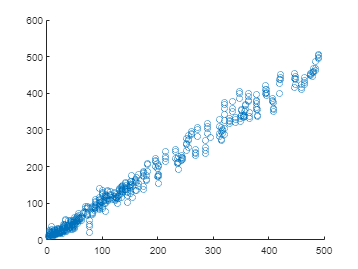


%display target vs pred
figure()
scatter(target.test,pred)

## Test on new Sensor

%Predict Test Data from newSensor
pred = tcocnnTest2.apply(dataRetrain.test);
disp(helpers.RMSE.loss(pred,target.test));

   93.3561



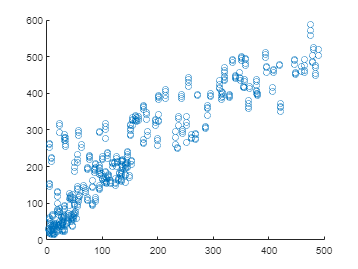


%display target vs pred
figure()
scatter(target.test,pred)

## Retrain the model

tcocnnTest2_Retrain = copy(tcocnnTest2);
retrainStruct = [];
retrainStruct.InitialLearnRate = optim.InitialLearnRate*0.9^15;
tcocnnTest2_Retrain.retrainFull(cat(4,dataRetrain.train,dataRetrain.val),[targetRetrain.train;targetRetrain.val],retrainStruct);

%Predict Test Data from newSensor
pred = tcocnnTest2_Retrain.apply(dataRetrain.test);
disp(helpers.RMSE.loss(pred,target.test));

   50.5958



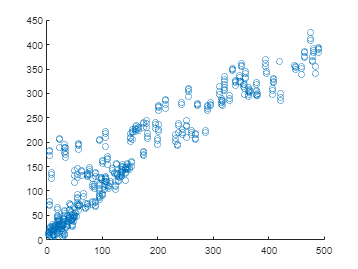


%display target vs pred
figure()
scatter(target.test,pred)